Reference:

Static, Vibration Analysis and Sensitivity Analysis of Stepped Beams Using Singularity Functions 

by Peng Cheng, Carla Davila and Gene Hou

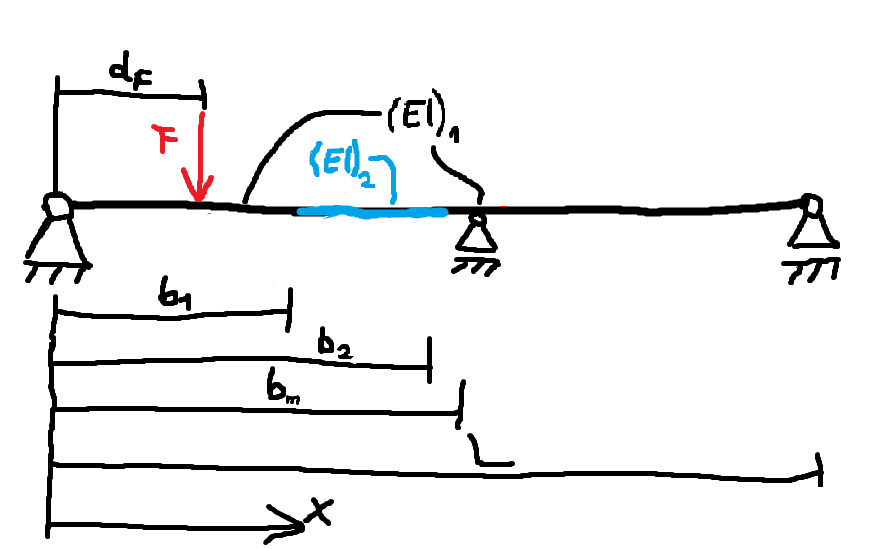

function [w,dw,ddw,M] = twoFieldBeam(x_val, E_val, L_val, d_F_val, F_val, I_val, b_val, b_m_val,bc_left,bc_right)

**Input**

x_val .. value for beam position in m

E_val .. value for elastic modulus in N/m^2

L_val .. value for beam length in m

d_F_val .. value for load position in m

F_val .. value for load in N

I_val=[I_1 I_2] .. value for second moment of area in m^4

b_val=[b_1 b_2] .. values for region of inhomogeneity in m

b_m_val .. value for midle support in m

bc_left .. boundary condition left side ('pinned' or 'fixed'); default value is 'pinned'

bc_right .. boundary condition left side ('pinned' or 'fixed'); default value is 'pinned'

**Output**

w .. displacement

dw .. first derivative of displacement (rotation)

ddw .. second derivative of displacement (curvature)

M .. bending moment

**Assumptions:**

$0 \leq L$, $0\leq E$, $0 \leq I_1$, $0 \leq I_2$

$0 \leq x \leq L
$, $0 \leq b_\mathrm m \leq L
$, $0 \leq d_F \leq L
$


$$0 \leq b_1 < b_2 \leq L
$$


if ~exist('bc_left','var') || isempty(bc_left)
    bc_left='pinned';
end
if ~exist('bc_right','var') || isempty(bc_right)
    bc_right='pinned';
end

syms M x E L dF F
syms R_l R_r % support reaction for left and right support
syms(sym('b_',[1 2])) % position of irregularity
syms(sym('I_',[1 2])) % second moment of area

syms R_m b_m % middle support position and reaction
syms(sym('C_',[1 4])) % integration constants

sf_0(x) =    heaviside(x); % singularity function: step function
sf_1(x) = x.*heaviside(x); % singularity function: integration of step function

support reaction (for continuous beam)

R_l_sub=(F.*(L-dF))./L;
R_r_sub=(F.*dF)./L;

Bending moment

% bending moment for simple support beam
% M(x) =  R_l               *sf_1(x) - F*sf_1(x-dF)                   + R_r            *sf_1(x-L);
% bending moment for continuous beam
  M(x) = (R_l-R_m.*(L-b_m)./L).*sf_1(x) - F.*sf_1(x-dF) + R_m.*sf_1(x-b_m) + (R_r-R_m.*b_m./L).*sf_1(x-L) +C_1*x +C_2;

Reciprocal of moment of inertia 1/I(x)

invI(x) = 1./I_1 - (1./I_1-1./I_2).*sf_0(x-b_1) - (1./I_2-1./I_1).*sf_0(x-b_2);

Differential eq.

ddw(x)=M(x).*invI(x)./E;
 dw(x)=int(ddw,x) + C_3;
  w(x)=int( dw,x) + C_4;

Boundary conditions

if strcmp(bc_left,'pinned')
    eq1= w(0)==0;
    eq2= M(0)==0;
elseif strcmp(bc_left,'fixed')
    eq1=  w(0)==0;
    eq2= dw(0)==0;
else
    error('Unknown boundary condition.')
end
if strcmp(bc_right,'pinned')
    eq3= w(L)==0;
    eq4= M(L)==0;
elseif strcmp(bc_right,'fixed')
    eq3=  w(L)==0;
    eq4= dw(L)==0;
else
    error('Unknown boundary condition.')
end

bc=[eq1 eq2 eq3 eq4];

zeroTerms=[heaviside(b_1-L) heaviside(b_2-L) heaviside(x-L) heaviside(dF-L) ...
          heaviside(-b_1) heaviside(-b_2) heaviside(-L) heaviside(-dF) heaviside(-b_m) ...
          ];
oneTerms=[heaviside(L) heaviside(L-b_1) heaviside(L-b_2) heaviside(L-x) heaviside(L-dF) heaviside(L-b_m) ...
           sign(L-b_1) sign(L-b_2) sign(L) sign(b_1) sign(b_2) ...
           heaviside(b_1) heaviside(b_2) heaviside(x)];
bc=subs(bc,zeroTerms,zeros(size(zeroTerms)));

bc=subs(bc,oneTerms,ones(size(oneTerms)));

Solve the diff. eq.

bc_sol=solve(bc,[C_1 C_2 C_3 C_4]);

Substitute constants

  w(x)=subs(  w(x),[C_1 C_2 C_3 C_4],struct2array(bc_sol));
 dw(x)=subs( dw(x),[C_1 C_2 C_3 C_4],struct2array(bc_sol));
ddw(x)=subs(ddw(x),[C_1 C_2 C_3 C_4],struct2array(bc_sol));
  M(x)=subs(  M(x),[C_1 C_2 C_3 C_4],struct2array(bc_sol));

Substitute bearing reactions

  w(x)=subs(  w(x),[R_l R_r],[R_l_sub R_r_sub]);
 dw(x)=subs( dw(x),[R_l R_r],[R_l_sub R_r_sub]);
ddw(x)=subs(ddw(x),[R_l R_r],[R_l_sub R_r_sub]);
  M(x)=subs(  M(x),[R_l R_r],[R_l_sub R_r_sub]);

Substitution of variables with values

vars=[F     dF     I_1      I_2      b_1      b_2      L     E     b_m];
vals=[F_val d_F_val I_val(1) I_val(2) b_val(1) b_val(2) L_val E_val b_m_val];

  w(x)=subs(  w(x),vars,vals);
 dw(x)=subs( dw(x),vars,vals);
ddw(x)=subs(ddw(x),vars,vals);  
  M(x)=subs(  M(x),vars,vals);

Boundary cond. for middle support

eq=w(b_m_val)==0;
R_m_sol=solve(eq,R_m);

Substitution of variables with values

  w(x)=subs(  w(x),R_m,R_m_sol);
 dw(x)=subs( dw(x),R_m,R_m_sol);
ddw(x)=subs(ddw(x),R_m,R_m_sol);
  M(x)=subs(  M(x),R_m,R_m_sol);

ddw=subs(ddw(x),x,x_val);
 dw=subs( dw(x),x,x_val);
  w=subs(  w(x),x,x_val);
  M=subs(  M(x),x,x_val);
